José Francisco Altamirano Zevallos

m1 = .05;
m2 = .05;
k1 = .01;
k2 = .01;
k3 = .01;
b = .0125;
x10y10x20y20 = [.025;0;.025;0]

x10y10x20y20 =     0.0250
         0
    0.0250
         0


Las ecuaciones de segundo orden reescritas se ven:

x1' = y1

y1' = (-by1 - (k1+k2)x1+k2x2)/m1

x2' = y2

y2' = (-by2 - (k2+k3)x2+k2x1)/m2

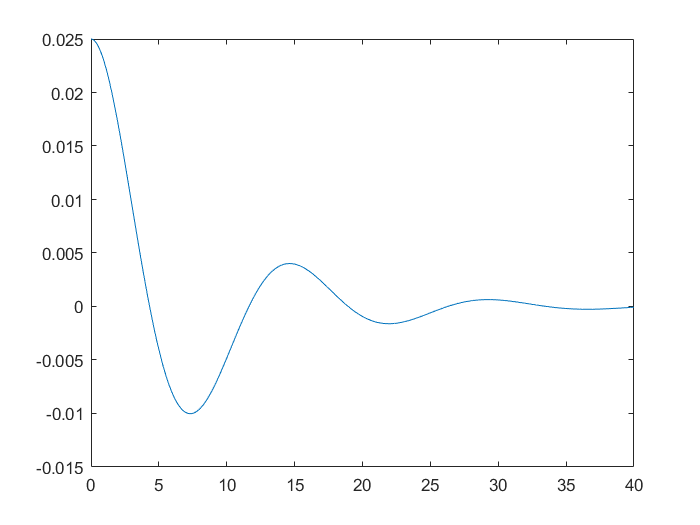

M = [0, 1, 0, 0; -((k1+k2)/m1), -(b/m1), (k2/m1), 0; 0, 0, 0, 1; (k2/m2), 0, -((k2+k3)/m2), -(b/m2)];
f = @(t,y) M*y;
[t,y] = ivps(f,0,40,x10y10x20y20,h,4);
plot(t,y(1,:));


%Para la frecuencia:
lambda = eig(M);

lambda =   -0.1250 + 0.7644i
  -0.1250 - 0.7644i
  -0.1250 + 0.4294i
  -0.1250 - 0.4294i


w = imag(lambda(:,1));

w =     0.7644
   -0.7644
    0.4294
   -0.4294


f = w/(2*pi);

f =     0.1217
   -0.1217
    0.0683
   -0.0683


T = 1/f;

T =     8.2193         0         0         0
